# Synthetic EEG + Behavioral States + ERPs (Teaching Live Script)

***Goal:**** Create a *synthetic** EEG signal that illustrates:

- Common EEG rhythms (delta/theta/alpha/beta/gamma) - How mixtures of rhythms can **suggest** behavioral states (eyes open/closed, drowsy, N2-like, REM-like) - Common artifacts (blink/EOG-like, EMG, line noise) - Event-related potentials (ERPs/EPs) and how averaging recovers them

--- ## Interpretation box (read me first) ***This is a teaching model.**** Real EEG interpretation is *probabilistic** and context-dependent. - Band power patterns are **suggestive**, not definitive. - Artifacts can mimic “brain” rhythms (e.g., muscle -> beta/gamma; blinks -> slow waves). - ERPs depend on stimulus timing, task design, referencing, montage, filtering, and trial counts.

You can convert this script to a Live Script: ***MATLAB**** → *Save As** → ***MATLAB Live Script (*.mlx)***

clear; close all; clc;

## 1) Global settings

Sampling rate and time axis

fs = 250;                 % Hz
dt = 1/fs;
T  = 120;                 % seconds total
t  = (0:dt:T-dt);
N  = numel(t);

% Channel label (single-channel demo; imagine posterior midline like Pz)
chanName = "Pz (synthetic)";

% Line noise: Canada is typically 60 Hz
lineHz = 60;

% Reproducibility
rng(1);

## 2) Define behavioral state schedule

We define **numeric** segment start/end times and **string** labels separately. This avoids the MATLAB pitfall: mixing numbers & strings in one array turns everything into strings.

segStart = [0,   20,  45,  70, 100];
segEnd   = [20,  45,  70, 100, 120];
segLabel = ["Awake EO", "Awake EC", "Drowsy", "N2-like", "REM-like"];

% Create per-sample state labels
state = strings(1,N);
for i = 1:numel(segStart)
    idx = (t >= segStart(i)) & (t < segEnd(i));
    state(idx) = segLabel(i);
end

## 3) Build canonical rhythms (oscillators + slow amplitude modulation)

EEG rhythms are not perfect sinusoids, but sinusoids are a good teaching proxy. We'll include a slow amplitude modulation to make them feel less “machine-like”.

makeRhythm = @(f0, amp_uV, amHz, phase0) ...
    (amp_uV .* (1 + 0.4*sin(2*pi*amHz*t)) .* sin(2*pi*f0*t + phase0));

delta = makeRhythm(2.0, 15, 0.10, 2*pi*rand);   % 0.5–4 Hz
theta = makeRhythm(6.0, 10, 0.12, 2*pi*rand);   % 4–8 Hz
alpha = makeRhythm(10,  12, 0.08, 2*pi*rand);   % 8–13 Hz
beta  = makeRhythm(20,   6, 0.20, 2*pi*rand);   % 13–30 Hz
gamma = makeRhythm(40,   2, 0.30, 2*pi*rand);   % 30–80 Hz (small)

## 4) Add 1/f-ish background activity (pink-ish noise)

Real EEG has scale-free background components. We'll approximate 1/f noise by filtering white noise with a leaky integrator (illustrative, not a perfect pink noise generator).

w = randn(1,N);
pinkish = filter(1, [1 -0.995], w);
pinkish = pinkish / std(pinkish);   % normalize

## 5) State-dependent mixing of rhythms

Here’s the “model”: each behavioral state is represented by a different **mixture** of rhythms.

--- ## Interpretation box: typical (not absolute) correlates - ***Awake eyes closed:**** alpha increases (especially posterior). - **Awake eyes open:**** alpha decreases; beta/EMG artifacts often rise. - **Drowsy:**** theta increases. - **N2 sleep:**** delta increases; spindles and K-complexes can appear. - **REM-like:*** theta-ish activity; interpretation needs EOG/EMG, not EEG alone.

eeg = zeros(1,N);

for k = 1:N
    s = state(k);

    % weights: [delta theta alpha beta gamma]
    switch s
        case "Awake EO"
            wts = [0.2 0.3 0.2 0.8 0.3];
        case "Awake EC"
            wts = [0.2 0.3 1.2 0.4 0.2];
        case "Drowsy"
            wts = [0.4 1.0 0.4 0.2 0.1];
        case "N2-like"
            wts = [1.1 0.5 0.1 0.1 0.0];
        case "REM-like"
            wts = [0.2 0.9 0.1 0.2 0.1];
        otherwise
            wts = [0.2 0.2 0.2 0.2 0.1];
    end

    eeg(k) = ...
        wts(1)*delta(k) + wts(2)*theta(k) + wts(3)*alpha(k) + ...
        wts(4)*beta(k)  + wts(5)*gamma(k);
end

% Add background noise (uV)
eeg = eeg + 4 * pinkish;

## 6) Add N2-like transients (spindles and K-complexes)

These are **illustrative** features. In real EEG: - Spindles: ~12–15 Hz bursts lasting ~0.5–2 s - K-complex: large slow biphasic waveform often in N2

spindle  = zeros(1,N);
kcomplex = zeros(1,N);

isN2 = (state == "N2-like");

% Spindles
spindleCenters = [75, 83, 92, 97];  % seconds
for c = spindleCenters
    burst = exp(-0.5*((t - c)/0.6).^2);
    osc   = sin(2*pi*13.5*t + 2*pi*rand);
    spindle = spindle + 10 * burst .* osc;
end
spindle(~isN2) = 0;

% K-complexes
kCenters = [88, 95];
for c = kCenters
    g1 = exp(-0.5*((t - c)/0.20).^2);
    g2 = exp(-0.5*((t - (c+0.25))/0.25).^2);
    kcomplex = kcomplex + 40*(g1 - 0.8*g2);
end
kcomplex(~isN2) = 0;

eeg = eeg + spindle + kcomplex;

## 7) Add common artifacts: blink/EOG-like, EMG, line noise

--- ## Interpretation box: why artifacts matter - ***Blinks/EOG**** produce large slow deflections and can masquerade as delta/theta. - **Muscle/EMG**** produces broadband high-frequency power (often beta/gamma). - **Line noise*** creates narrow peaks at 50/60 Hz and harmonics.

% Eye blinks (big slow transients)
blink = zeros(1,N);
blinkTimes = [8, 18, 28, 34, 52, 62, 108]; % seconds
for bt = blinkTimes
    shape = exp(-0.5*((t - bt)/0.10).^2);
    blink = blink + 80*shape;
end

% EMG-like noise (band-limited high frequency), stronger during awake
emg = randn(1,N);
emg = bandpass(emg, [30 90], fs);
emg = emg / std(emg);

emgScale = zeros(1,N);
emgScale(state=="Awake EO") = 6;
emgScale(state=="Awake EC") = 3;
emgScale(state=="Drowsy")   = 2;
emgScale(state=="N2-like")  = 1;
emgScale(state=="REM-like") = 2;

emg = emg .* emgScale;

% Line noise (60 Hz)
lineNoise = 2.0 * sin(2*pi*lineHz*t);

% Combine into observed raw EEG
eeg_raw = eeg + blink + emg + lineNoise;

## 8) Create events and inject ERPs (EPs)

We simulate a simple oddball task: - Many "standard" stimuli (sensory ERP only) - Rare "target" stimuli (sensory ERP + P3)

We'll model ERP components with Gaussian peaks: - P1 ~100 ms, N1 ~170 ms, P2 ~230 ms, P3 ~350 ms (targets)

--- ## Interpretation box: what “EPs/ERPs” mean An ERP is **not** a separate signal; it is a small, time-locked component embedded in ongoing EEG. Averaging across trials reduces unrelated activity and reveals the time-locked waveform.

eventRateHz = 0.7;          % events per second
nEvents = round(eventRateHz * T);

epochPre  = 0.2;            % sec
epochPost = 0.8;            % sec
minT = epochPre + 0.5;
maxT = T - (epochPost + 0.5);

evTimes = sort(minT + (maxT-minT)*rand(1,nEvents));

% Oddball targets ~15%
isTarget = rand(1,nEvents) < 0.15;

% ERP waveform generator on local epoch time te (sec; 0 at event onset)
erpWave = @(te, ampScale, includeP3) ...
    ampScale * ( ...
        + 6*exp(-0.5*((te-0.10)/0.03).^2) ...   % P1
        - 8*exp(-0.5*((te-0.17)/0.04).^2) ...   % N1
        + 5*exp(-0.5*((te-0.23)/0.05).^2) ...   % P2
        + (includeP3 * 10*exp(-0.5*((te-0.35)/0.08).^2)) ... % P3 (targets)
    );

% Inject ERPs into the observed EEG (state-dependent amplitude)
eeg_obs = eeg_raw;
for i = 1:nEvents
    t0 = evTimes(i);
    idx0 = round(t0*fs) + 1;

    preSamp  = round(epochPre*fs);
    postSamp = round(epochPost*fs);

    idx1 = idx0 - preSamp;
    idx2 = idx0 + postSamp;

    if idx1 < 1 || idx2 > N
        continue;
    end

    te = (-preSamp:postSamp)/fs;

    % ERP amplitude depends on behavioral state (illustrative)
    s = state(idx0);
    switch s
        case {"Awake EO","Awake EC"}
            ampScale = 1.0;
        case "Drowsy"
            ampScale = 0.7;
        case "REM-like"
            ampScale = 0.6;
        case "N2-like"
            ampScale = 0.25;
        otherwise
            ampScale = 0.6;
    end

    eeg_obs(idx1:idx2) = eeg_obs(idx1:idx2) + erpWave(te, ampScale, isTarget(i));
end

## 9) Visualize raw EEG with state annotations

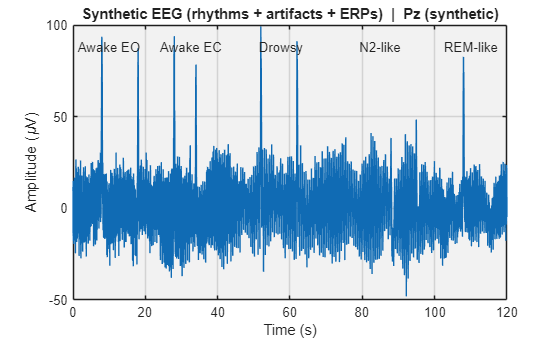

figure('Name','Synthetic EEG (Observed)','Color','w');
plot(t, eeg_obs);
xlabel('Time (s)'); ylabel('Amplitude (\muV)');
title("Synthetic EEG (rhythms + artifacts + ERPs)  |  " + chanName);
grid on;

% Shade state segments + labels
yl = ylim; hold on;
for i = 1:numel(segStart)
    x1 = segStart(i); x2 = segEnd(i);
    patch([x1 x2 x2 x1],[yl(1) yl(1) yl(2) yl(2)], ...
          [0 0 0], 'FaceAlpha', 0.05, 'EdgeColor', 'none');
    text((x1+x2)/2, yl(2)-0.08*(yl(2)-yl(1)), segLabel(i), ...
         'HorizontalAlignment','center','FontSize',10);
end
hold off;

## 10) Spectral view: PSD by state + bandpower table

We use Welch’s method to estimate power spectral density and then compute bandpower.

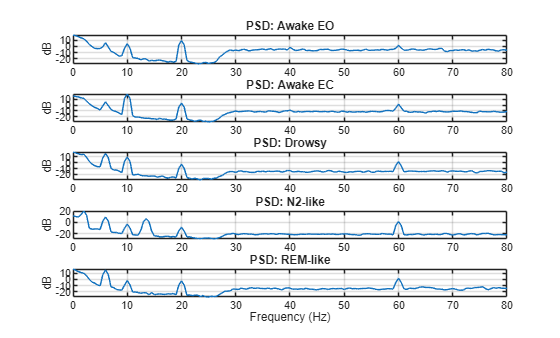

bands = [0.5 4; 4 8; 8 13; 13 30; 30 70];
bandNames = ["Delta","Theta","Alpha","Beta","Gamma"];

figure('Name','PSD by State','Color','w');
for i = 1:numel(segStart)
    idx = (t >= segStart(i)) & (t < segEnd(i));
    x = eeg_obs(idx);

    [Pxx,F] = pwelch(x, hamming(2*fs), fs, 0:0.5:80, fs);

    subplot(numel(segStart),1,i);
    plot(F, 10*log10(Pxx));
    xlim([0 80]); grid on;
    ylabel('dB');
    title("PSD: " + segLabel(i));
    if i == numel(segStart), xlabel('Frequency (Hz)'); end
end


% Bandpower summary table
bp = zeros(numel(segStart), numel(bandNames));
for i = 1:numel(segStart)
    idx = (t >= segStart(i)) & (t < segEnd(i));
    x = eeg_obs(idx);
    for b = 1:size(bands,1)
        bp(i,b) = bandpower(x, fs, bands(b,:));
    end
end
bpTable = array2table(bp, 'VariableNames', cellstr(bandNames));
bpTable.State = segLabel(:);
bpTable = movevars(bpTable, "State", "Before", 1);

disp("Bandpower summary (arbitrary units):");

Bandpower summary (arbitrary units):


disp(bpTable);

      State       Delta     Theta      Alpha      Beta      Gamma 
    __________    ______    ______    _______    _______    ______

    "Awake EO"    93.559    6.4446     2.8888     13.414    25.746
    "Awake EC"    121.33    6.2183     106.16     3.3668    7.6868
    "Drowsy"       108.5    53.294     11.728    0.96013     4.795
    "N2-like"     168.88     13.57    0.82295     6.4332    2.6551
    "REM-like"    88.981    46.495    0.75902    0.94819    4.6373



## 11) Epoching and ERP recovery (standards vs targets)

We epoch around each event, baseline-correct, then average.

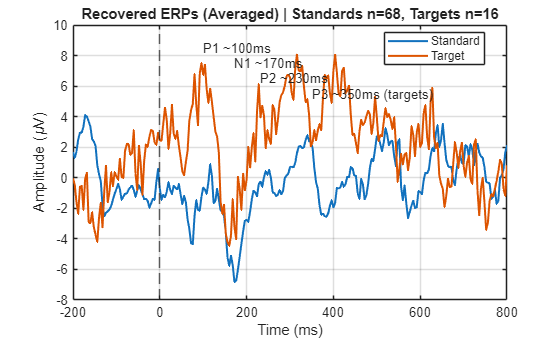

preSamp  = round(epochPre*fs);
postSamp = round(epochPost*fs);
te = (-preSamp:postSamp)/fs;   % seconds

epochsStd = [];
epochsTgt = [];

for i = 1:nEvents
    idx0 = round(evTimes(i)*fs) + 1;
    idx1 = idx0 - preSamp;
    idx2 = idx0 + postSamp;
    if idx1 < 1 || idx2 > N, continue; end

    ep = eeg_obs(idx1:idx2);

    % Baseline correction using pre-stim interval
    ep = ep - mean(ep(1:preSamp));

    if isTarget(i)
        epochsTgt(:,end+1) = ep; %#ok<SAGROW>
    else
        epochsStd(:,end+1) = ep; %#ok<SAGROW>
    end
end

erpStd = mean(epochsStd, 2);
erpTgt = mean(epochsTgt, 2);

figure('Name','Recovered ERPs','Color','w');
plot(te*1000, erpStd, 'LineWidth', 1.5); hold on;
plot(te*1000, erpTgt, 'LineWidth', 1.5);
xline(0, '--'); grid on;
xlabel('Time (ms)'); ylabel('Amplitude (\muV)');
title(sprintf('Recovered ERPs (Averaged) | Standards n=%d, Targets n=%d', ...
    size(epochsStd,2), size(epochsTgt,2)));
legend('Standard','Target','Location','best');

% Mark canonical component labels (illustrative)
yl = ylim;
text(100, yl(2)*0.85, 'P1 ~100ms');
text(170, yl(2)*0.75, 'N1 ~170ms');
text(230, yl(2)*0.65, 'P2 ~230ms');
text(350, yl(2)*0.55, 'P3 ~350ms (targets)');

## 12) Optional: Spectrogram for time-varying rhythms

Spectrogram helps you **see** when rhythms change over time (state transitions, spindles).

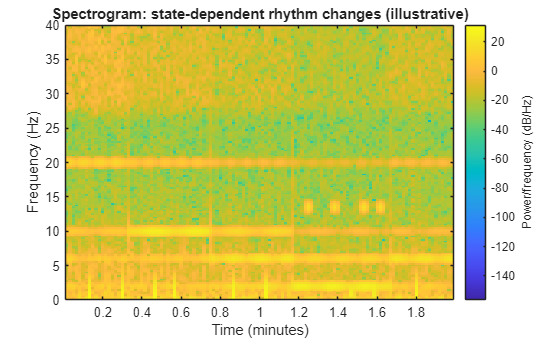

figure('Name','Spectrogram','Color','w');
win = 2*fs;          % 2-second window
noverlap = fs;       % 50% overlap
nfft = 4*fs;

spectrogram(eeg_obs, win, noverlap, nfft, fs, 'yaxis');
ylim([0 40]); % focus on 0–40 Hz
title('Spectrogram: state-dependent rhythm changes (illustrative)');

## 13) Exercises (quick ways to learn from the model)

1) Increase alpha in eyes closed: change the "Awake EC" alpha weight. 2) Make EMG worse in eyes open: raise emgScale for "Awake EO". 3) Reduce P3 amplitude or target probability and see how many trials are needed to recover it. 4) Try notch filtering at 60 Hz and see the PSD peak shrink. 5) Add a second "channel" (e.g., Fz) with stronger blinks and smaller alpha, then compare.

disp("Done. Tip: Save As -> Live Script (.mlx) to get a polished teaching notebook.");

Done. Tip: Save As -> Live Script (.mlx) to get a polished teaching notebook.
